%clearing all data
clear all

%setting required symbolic variables
syms x

%question 1)

%importing raw data
planet = readtable('Planet_data_311021.csv')

planet = 9×4 table
       Body        solDistance_x10_9_m    mass_x10_22_kg    solOrbit_days_
    ___________    ___________________    ______________    ______________

    {'Mercury'}             58                    33               88     
    {'Venus'  }            108                   487            224.7     
    {'Earth'  }            150                   598            365.2     
    {'Mars'   }            228                  64.2              687     
    {'Jupiter'}            778               1.9e+05             4332     
    {'Saturn' }           1429                 56900            10760     
    {'Uranus' }           2871                  8690            30700     
    {'Neptune'}           4504                 10280            60200     
    {'Pluto'  }           5913                  1.49            90600     



%extracting height of table
count = height(planet);

%subsetting
%planet1 = planet(1:count,["solOrbit_days_","solDistance_x10_9_m"])

%subsetting and extracting x and y data (also converting from table to
%array)
x_pts = table2array(planet(1:count,["solDistance_x10_9_m"]));
y_pts = table2array(planet(1:count,["solOrbit_days_"]));

%plotting
plot(x_pts,y_pts,"r.",'MarkerSize', 15)

%fitting quadratic
fit_param = polyfit(x_pts,y_pts,2);

%printing fit_param
fit_param

fit_param =     0.0015    6.4477 -808.7723


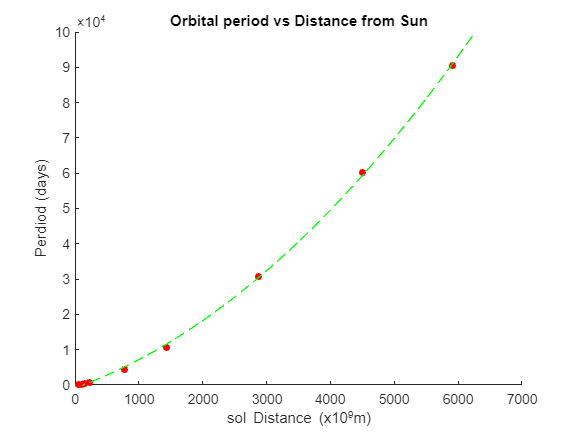


%setting quadratic parameters
a = fit_param(1);
b = fit_param(2);
c = fit_param(3);

%plotting quadratic
fit(x) = a*x^2 + b*x + c;

%ensuring fit can be plotted on same graph
hold on

%plotting fit
fplot(fit(x),"g--")
xlim([0 7000])
ylim([0 100000])

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%labelling gprah
xlabel("sol Distance (x10^9m)")
ylabel("Perdiod (days)")
title("Orbital period vs Distance from Sun")

%end of plotting function
hold off


%question 2)
%period of planet with distance 420 million km (result in days)
fit(420);
p10_T = eval(ans)

p10_T = 2.1705e+03


%question 3

%adding new columns
planet.orbVel_x10_9m_per_days = zeros(9,1);
planet.perC = zeros(9,1);

%value of c in 10^9m/day
c=(3*10^8)*(10^-9)*(60*60*24);

%looping through each row to add new col data
for i=1:1:count
    
    %extracting radius and period
    R = table2array(planet(i,["solDistance_x10_9_m"]));
    T = table2array(planet(i,["solOrbit_days_"]));

    %calculating V and fraction of speed of light
    V = 2*pi*(R/T);
    C_frac = V/c;

    %storing orbital velocty 
    planet(i,["orbVel_x10_9m_per_days"]) = array2table(V);
    planet(i,["perC"]) = array2table(C_frac);
end

%printing table
planet

planet = 9×6 table
       Body        solDistance_x10_9_m    mass_x10_22_kg    solOrbit_days_    orbVel_x10_9m_per_days       perC   
    ___________    ___________________    ______________    ______________    ______________________    __________

    {'Mercury'}             58                    33               88                 4.1412            0.00015977
    {'Venus'  }            108                   487            224.7                   3.02            0.00011651
    {'Earth'  }            150                   598            365.2                 2.5807            9.9565e-05
    {'Mars'   }            228                  64.2              687                 2.0852            8.0449e-05
    {'Jupiter'}            778               1.9e+05             4332                 